% load the extracted matrix variables
load("voltData_extracted.mat");

% Calculate statistics
meanVolt_NonShield_S = mean(voltData_NonShield_S, 2)

meanVolt_NonShield_S =     3.2706
    3.2720
    3.2716
    2.9003
    2.3470
    2.0707
    1.9318
    1.8527
    1.8022
    1.7698


meanVolt_NonShield_N = mean(voltData_NonShield_N, 2)

meanVolt_NonShield_N =     0.0642
    0.0685
    0.0766
    0.4131
    1.0173
    1.3011
    1.4462
    1.5328
    1.5836
    1.6128


meanVolt_Shield_S = mean(voltData_Shield_S, 2)

meanVolt_Shield_S =     3.2700
    3.2723
    3.0615
    2.5030
    2.1865
    1.9973
    1.8930
    1.8297
    1.7910
    1.7624


meanVolt_Shield_N = mean(voltData_Shield_N, 2)

meanVolt_Shield_N =     0.0743
    0.0763
    0.1286
    0.8401
    1.1891
    1.3723
    1.4812
    1.5489
    1.5864
    1.6154



stdVolt__NonShield_S = std(voltData_NonShield_S, 0, 2)

stdVolt__NonShield_S =     0.0016
    0.0014
    0.0014
    0.0068
    0.0098
    0.0093
    0.0094
    0.0085
    0.0085
    0.0083


stdVolt__NonShield_N = std(voltData_NonShield_N, 0, 2)

stdVolt__NonShield_N =     0.0017
    0.0017
    0.0017
    0.0042
    0.0050
    0.0049
    0.0049
    0.0050
    0.0052
    0.0054


stdVolt__Shield_S = std(voltData_Shield_S, 0, 2)

stdVolt__Shield_S =     0.0015
    0.0015
    0.0069
    0.0101
    0.0093
    0.0088
    0.0082
    0.0089
    0.0083
    0.0081


stdVolt__Shield_N = std(voltData_Shield_N, 0, 2)

stdVolt__Shield_N =     0.0017
    0.0016
    0.0020
    0.0049
    0.0049
    0.0048
    0.0048
    0.0060
    0.0052
    0.0050



measureX = 9 : 3 : 45

measureX =      9    12    15    18    21    24    27    30    33    36    39    42    45


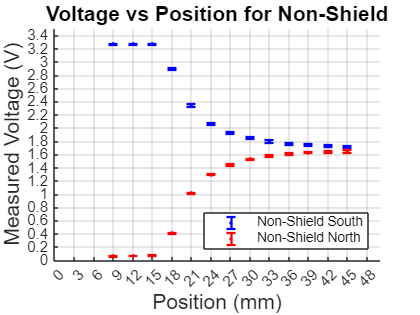

% Plotting Non-Shield
figure;
hold on;
graph_NonShield_S = errorbar(measureX, meanVolt_NonShield_S, 2*stdVolt__NonShield_S, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
graph_NonShield_N = errorbar(measureX, meanVolt_NonShield_N, 2*stdVolt__NonShield_N, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'r', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
% ตกแต่ง
xticks(0:3:50);
xticklabels(0:3:50);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Voltage vs Position for Non-Shield', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Measured Voltage (V)', 'FontSize', 14); 
legend('Non-Shield South', 'Non-Shield North','Location', 'southeast');

hold off;

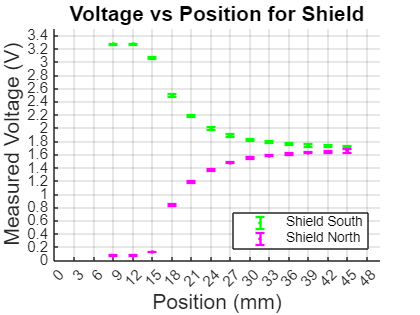

% Plotting Shield
figure;
hold on;
graph_Shield_S = errorbar(measureX, meanVolt_Shield_S, 2*stdVolt__Shield_S, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'g', 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');
graph_Shield_N = errorbar(measureX, meanVolt_Shield_N, 2*stdVolt__Shield_N, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'm', 'MarkerEdgeColor', 'm', 'MarkerFaceColor', 'm');
% ตกแต่ง
xticks(0:3:50);
xticklabels(0:3:50);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Voltage vs Position for Shield', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Measured Voltage (V)', 'FontSize', 14); 
legend('Shield South', 'Shield North','Location', 'southeast');

hold off;

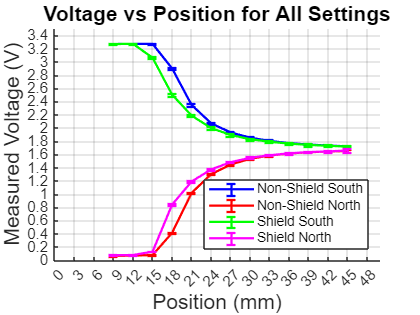

% plot all the 4 datasets

% Combined Plot for all four datasets
figure;
hold on;

% Plotting Non-Shield South
graph_NonShield_S = errorbar(measureX, meanVolt_NonShield_S, 2*stdVolt__NonShield_S, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');

% Plotting Non-Shield North
graph_NonShield_N = errorbar(measureX, meanVolt_NonShield_N, 2*stdVolt__NonShield_N, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'r', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');

% Plotting Shield South
graph_Shield_S = errorbar(measureX, meanVolt_Shield_S, 2*stdVolt__Shield_S, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'g', 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');

% Plotting Shield North
graph_Shield_N = errorbar(measureX, meanVolt_Shield_N, 2*stdVolt__Shield_N, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'm', 'MarkerEdgeColor', 'm', 'MarkerFaceColor', 'm');

% Customizing the plot
xticks(0:3:50);
xticklabels(0:3:50);
yticks(0:0.2:3.4);
yticklabels(0:0.2:3.4);
grid on;
title('Voltage vs Position for All Settings', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Measured Voltage (V)', 'FontSize', 14); 

% Adding legend for all four datasets
legend({'Non-Shield South', 'Non-Shield North', 'Shield South', 'Shield North'}, 'Location', 'southeast');

hold off;

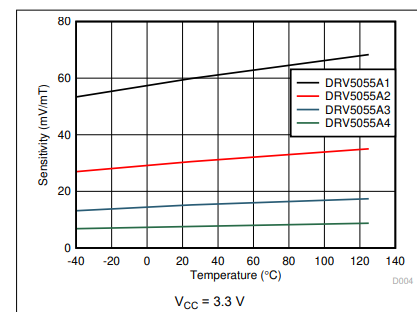

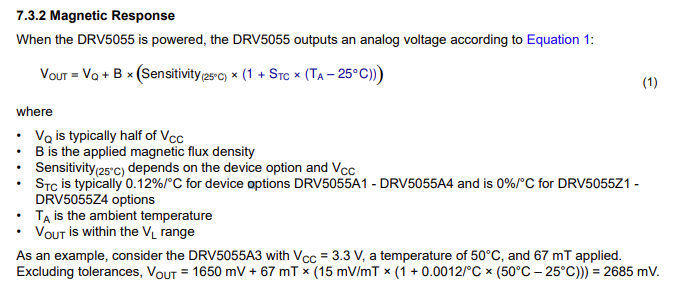

% function to convert V to B (Magnetic flux density)
function B = volt2B(voltage)
    V_Q = 3.3 / 2;
    Sensitivity = 30; % for 5055A3 read from DataSheet
    S_rc = 0.0012;
    T_A = 24;

    B = (voltage - V_Q) / (Sensitivity * (1 + S_rc * (T_A - 25)));
end

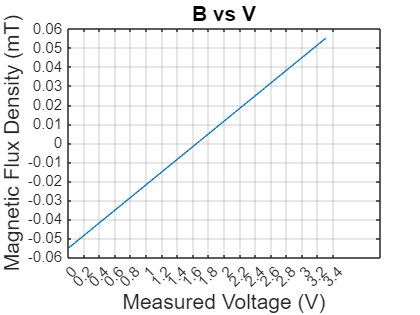

% plotting B vs V to see relationship

V_space = linspace(0, 3.3, 300);
B_space = volt2B(V_space);

figure;
plot(V_space, volt2B(V_space));
xticks(0:0.2:3.4);
xticklabels(0:0.2:3.4);
yticks(-0.08:0.01:0.08);
yticklabels(-0.08:0.01:0.08);
grid on;
grid on;
title('B vs V', 'FontSize', 14);
xlabel('Measured Voltage (V)', 'FontSize', 14); 
ylabel('Magnetic Flux Density (mT)', 'FontSize', 14); 

% plotting B vs X for Non-Shield
B_NonShield_S = volt2B(meanVolt_NonShield_S)

B_NonShield_S =     0.0541
    0.0541
    0.0541
    0.0417
    0.0233
    0.0140
    0.0094
    0.0068
    0.0051
    0.0040


B_NonShield_N = volt2B(meanVolt_NonShield_N)

B_NonShield_N =    -0.0529
   -0.0528
   -0.0525
   -0.0413
   -0.0211
   -0.0116
   -0.0068
   -0.0039
   -0.0022
   -0.0012


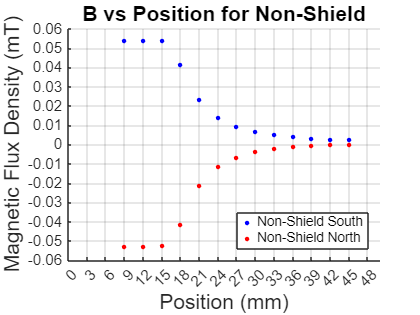


figure;
hold on;
graph_B_NonShield_S = plot(measureX, B_NonShield_S, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1.5, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');
graph_B_NonShield_N = plot(measureX, B_NonShield_N, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1.5, 'Color', 'r', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');
%plot(measureX, B_Non_NonShield_S)
%plot(measureX, B_Non_NonShield_N)

% ตกแต่ง
xticks(0:3:50);
xticklabels(0:3:50);
yticks(-0.08:0.01:0.08);
yticklabels(-0.08:0.01:0.08);
grid on;
title('B vs Position for Non-Shield', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Magnetic Flux Density (mT)', 'FontSize', 14); 
legend('Non-Shield South', 'Non-Shield North','Location', 'southeast');

hold off;

% plotting B vs X for Shield
B_Shield_S = volt2B(meanVolt_Shield_S)

B_Shield_S =     0.0541
    0.0541
    0.0471
    0.0285
    0.0179
    0.0116
    0.0081
    0.0060
    0.0047
    0.0038


B_Shield_N = volt2B(meanVolt_Shield_N)

B_Shield_N =    -0.0526
   -0.0525
   -0.0508
   -0.0270
   -0.0154
   -0.0093
   -0.0056
   -0.0034
   -0.0021
   -0.0012


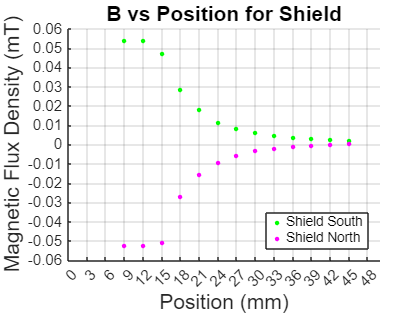


figure;
hold on;
graph_B_Shield_S = plot(measureX, B_Shield_S, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1.5, 'Color', 'g', 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');
graph_B_Shield_N = plot(measureX, B_Shield_N, ...
    'or', 'LineWidth', 1.5, 'MarkerSize', 1.5, 'Color', 'm', 'MarkerEdgeColor', 'm', 'MarkerFaceColor', 'm');

% ตกแต่ง
xticks(0:3:50);
xticklabels(0:3:50);
yticks(-0.08:0.01:0.08);
yticklabels(-0.08:0.01:0.08);
grid on;
title('B vs Position for Shield', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Magnetic Flux Density (mT)', 'FontSize', 14); 
legend('Shield South', 'Shield North','Location', 'southeast');

hold off;

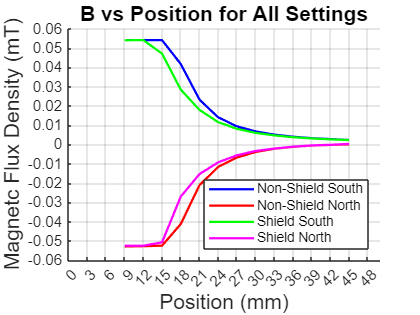

% plot all the 4 datasets for B vs X

% Combined Plot for all four datasets
figure;
hold on;

% Plotting Non-Shield South
graph_B_NonShield_S = plot(measureX, B_NonShield_S, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'b', 'MarkerEdgeColor', 'b', 'MarkerFaceColor', 'b');

% Plotting Non-Shield North
graph_B_NonShield_N = plot(measureX, B_NonShield_N, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'r', 'MarkerEdgeColor', 'r', 'MarkerFaceColor', 'r');

% Plotting Shield South
graph_B_Shield_S = plot(measureX, B_Shield_S, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'g', 'MarkerEdgeColor', 'g', 'MarkerFaceColor', 'g');

% Plotting Shield North
graph_B_Shield_N = plot(measureX, B_Shield_N, ...
    '', 'LineWidth', 1.5, 'MarkerSize', 1, 'Color', 'm', 'MarkerEdgeColor', 'm', 'MarkerFaceColor', 'm');

% Customizing the plot
xticks(0:3:50);
xticklabels(0:3:50);
yticks(-0.08:0.01:0.08);
yticklabels(-0.08:0.01:0.08);
grid on;
title('B vs Position for All Settings', 'FontSize', 14);
xlabel('Position (mm)', 'FontSize', 14); 
ylabel('Magnetc Flux Density (mT)', 'FontSize', 14); 

% Adding legend for all four datasets
legend({'Non-Shield South', 'Non-Shield North', 'Shield South', 'Shield North'}, 'Location', 'southeast');

hold off;

% print tables
position = measureX'

position =      9
    12
    15
    18
    21
    24
    27
    30
    33
    36


table(position, meanVolt_NonShield_S, stdVolt__NonShield_S, B_NonShield_S)

ans = 13×4 table
    position    meanVolt_NonShield_S    stdVolt__NonShield_S    B_NonShield_S
    ________    ____________________    ____________________    _____________

        9              3.2706                0.0015514             0.054086  
       12               3.272                0.0014263             0.054131  
       15              3.2716                0.0014397             0.054119  
       18              2.9003                0.0067887             0.041727  
       21               2.347                0.0097706             0.023263  
       24              2.0707                0.0092608             0.014039  
       27              1.9318                0.0094059            0.0094047  
       30              1.8527                0.0085164            0.0067638  
       33              1.8022                0.0084981            

table(position, meanVolt_NonShield_N, stdVolt__NonShield_N, B_NonShield_N)

ans = 13×4 table
    position    meanVolt_NonShield_N    stdVolt__NonShield_N    B_NonShield_N
    ________    ____________________    ____________________    _____________

        9             0.064247               0.0016681             -0.052922 
       12             0.068493               0.0016934              -0.05278 
       15             0.076575               0.0016667             -0.052511 
       18              0.41308               0.0041976              -0.04128 
       21               1.0173               0.0049603             -0.021117 
       24               1.3011                0.004868             -0.011645 
       27               1.4462               0.0049264            -0.0068015 
       30               1.5328               0.0050367            -0.0039117 
       33               1.5836               0.0052418            

table(position, meanVolt_Shield_S, stdVolt__Shield_S, B_Shield_S)

ans = 13×4 table
    position    meanVolt_Shield_S    stdVolt__Shield_S    B_Shield_S
    ________    _________________    _________________    __________

        9              3.27              0.0015344         0.054065 
       12            3.2723              0.0014692         0.054141 
       15            3.0615              0.0069012         0.047108 
       18             2.503               0.010113         0.028469 
       21            2.1865              0.0093031         0.017905 
       24            1.9973              0.0087816         0.011589 
       27             1.893              0.0082238        0.0081089 
       30            1.8297              0.0088935        0.0059973 
       33             1.791              0.0083496        0.0047063 
       36            1.7624              0.0081222        0.0037505 
       39         

table(position, meanVolt_Shield_N, stdVolt__Shield_N, B_Shield_N)

ans = 13×4 table
    position    meanVolt_Shield_N    stdVolt__Shield_N    B_Shield_N 
    ________    _________________    _________________    ___________

        9           0.074338             0.0017184          -0.052585
       12            0.07629             0.0015995           -0.05252
       15            0.12857             0.0019722          -0.050775
       18            0.84007             0.0048994           -0.02703
       21             1.1891             0.0048709           -0.01538
       24             1.3723             0.0048355         -0.0092666
       27             1.4812             0.0048077         -0.0056324
       30             1.5489              0.006022         -0.0033752
       33             1.5864              0.005193         -0.0021214
       36             1.6154             0.0049951         -0.0011562
      